clear
tic

% Import data from text file
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp.csv");
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_06_Sun_13_59_53.csv");
%TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_07_Mon_10_00_49.csv");
TimeTemp = readtable("\\apporto.com\dfs\UHCL\Users\1915097_uhcl\Documents\Thesis\TimeTemp_2026_Sep_08_Tue_14_31_01.csv");
toc

Elapsed time is 1.768852 seconds.


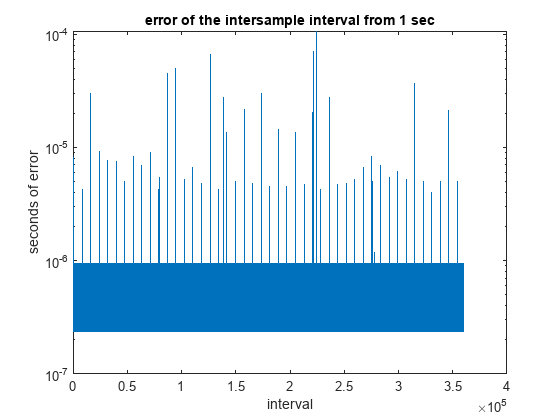

% Calculate intersample interval
dt = diff(TimeTemp{:,"now"});

% Plot the intersample interval
figure(); plot(dt-1);title("error of the intersample interval from 1 sec"); ylabel("seconds of error");xlabel("interval");
set(gca,'XScale','linear','YScale','log');

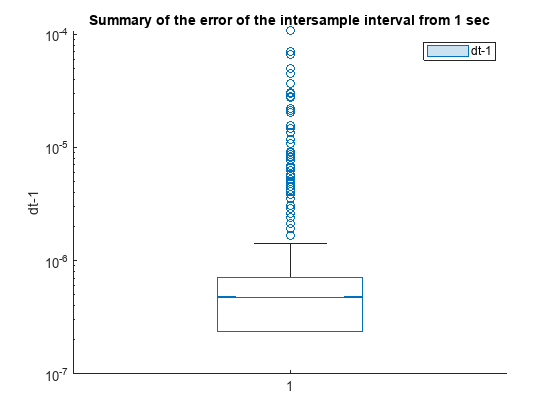


% % Create boxchart of dt
figure(); boxchart(dt-1,'Notch','on',"DisplayName","dt-1");
% Add ylabel, title, and legend
ylabel("dt-1");
title("Summary of the error of the intersample interval from 1 sec")
set(gca,'YScale','log');
legend

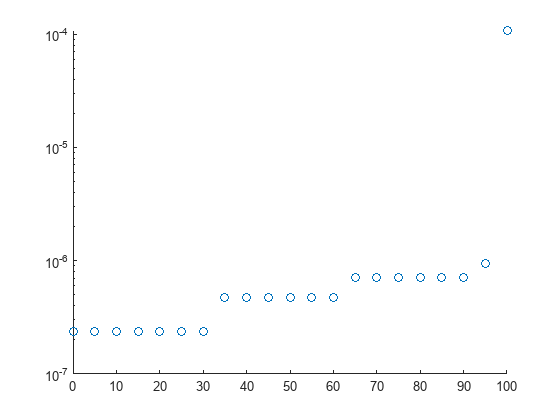


percentiles = 0:5:100;
figure();
scatter(percentiles,prctile(dt-1,percentiles));
set(gca,'XScale','linear','YScale','log');

toc

Elapsed time is 2.334010 seconds.


%compute the Allan Variance of the Intersample Interval Duration with a 
dt_tau = 1:100:height(dt)/2;
time0=toc

time0 = 3.5183

dt_avar=allanvar(dt,dt_tau); % tau channel
% time1=toc
% dt_avarcust=allanVarCustom(dt,dt_tau)
% time2=toc
% dt_avarvec=allanVarVectorized(dt,dt_tau)
% time3=toc
% runtime1 = time1-time0
% runtime2 = time2-time1
% runtime3 = time3-time2
%Compute the slope of the clock Allan Variance over Tau
idx = dt_tau >= 1 & dt_tau <= 1000;   % sample region

% linear fit in log10-log10 space; 
p = polyfit(log10(dt_tau(idx)), log10(dt_avar(idx)), 1);

%create the best fit line
yfit = 10.^(p(1)*log10(dt_tau) + p(2)); 

%Predict the taus
predictionTaus = 10.^[0;1;2;3;4;5;6];
predictedJitter = 10.^(p(1)*log10(predictionTaus) + p(2));
table(predictionTaus,predictedJitter)

ans = 7×2 table
    predictionTaus    predictedJitter
    ______________    _______________

            1           1.4016e-13   
           10           1.4686e-14   
          100           1.5388e-15   
         1000           1.6123e-16   
        10000           1.6893e-17   
        1e+05             1.77e-18   
        1e+06           1.8546e-19   


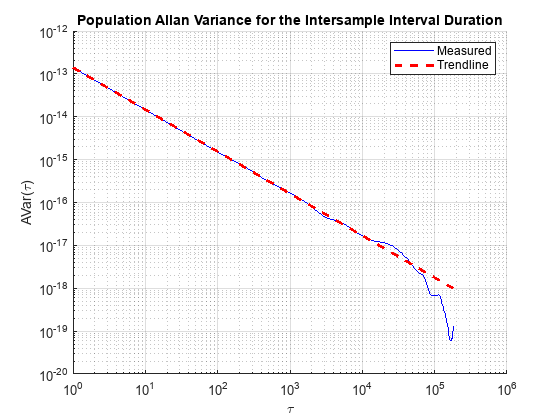


%Plot the Allan Variance of the clock
figure(); hold on;
plot(dt_tau, dt_avar, 'b');
% scatter(dt_tau,dt_avarcust,'g');
%scatter(dt_tau,dt_avarvec,"cyan")
plot(dt_tau, yfit, 'r--', 'LineWidth', 2);
title("Population Allan Variance for the Intersample Interval Duration");
xlabel('\tau'); ylabel('AVar(\tau)');
legend("Measured", "Trendline");
set(gca,'XScale','log','YScale','log');
grid on;hold off;

disp("LogLog Slope:" + p(1)) % p(1) = slope;

LogLog Slope:-0.97973


disp("LogLog Intercept:" + p(2)) % p(2) = intercept;

LogLog Intercept:-12.8534


disp("AVAR(\tau)=" + p(2) +"\tau^"+ p(1))

AVAR(\tau)=-12.8534\tau^-0.97973


toc

Elapsed time is 6.923843 seconds.


%Create a shortcut to point to the rawdata
allsensors = ["Temp1","Temp2","Temp3","Temp4","Temp5","Temp6","Temp7","Temp8"];
%take the moving average after eliminating outliers from the moving median
% 0. Compute the Per Row Median
TimeTemp{:,"median"}=median(TimeTemp{:,allsensors},2);
% 1. Compute deviation from median
TimeTemp{:,"MedianDifference"} = abs(TimeTemp{:,allsensors} - TimeTemp{:,"median"});
% 2. Build mask of good sensors
TimeTemp{:,"mask"} = TimeTemp{:,"MedianDifference"} <= 0.25;   % Nx8 logical
% 3. Zero out bad sensors
TimeTemp{:,"goodVals"} = TimeTemp{:,allsensors} .* TimeTemp{:,"mask"};
% 4. Count good sensors per row
TimeTemp{:,"numGood"} = sum(TimeTemp{:,"mask"}, 2);
% 5. Compute robust average
robustAvg = sum(TimeTemp{:,"goodVals"}, 2) ./ TimeTemp{:,"numGood"};
% 6. Handle rows with zero good sensors
robustAvg(TimeTemp{:,"numGood"} == 0) = NaN;
TimeTemp{:,"robustAvg"}=robustAvg;

clear robustAvg

%human readable datetime
TimeTemp{:,"Days1"} = datetime(TimeTemp{1,"now"},'ConvertFrom','posixtime','timezone','America/Chicago');
TimeTemp{:,"Days"} = TimeTemp{:,"now"}/(60*60*24) + datenum(1970,1,1,-5,0,0);%use a -5 offset for UCT to CST
%TimeTemp{:,"DeltaT"}=TimeTemp{:,"now"}-TimeTemp{1,"now"}; %Calculate 

toc 

Elapsed time is 7.969431 seconds.


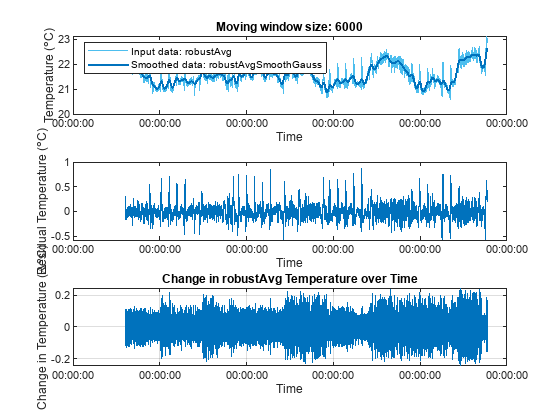

% Smooth robustAvg data
[TimeTemp.robustAvgSmoothGauss,winSize] = smoothdata(TimeTemp{:,"robustAvg"},"gaussian",6000, ...
    "SamplePoints",TimeTemp.now);
TimeTemp.ResidualTemperatureNoise = TimeTemp.robustAvg-TimeTemp.robustAvgSmoothGauss;

TimeTemp.TemperatureChange = [0;diff(TimeTemp{:,"robustAvg"})]; %Plot the point to point difference


% Display results
figure();
subplot(3,1,1)
plot(TimeTemp.Days,TimeTemp.robustAvg,"SeriesIndex",6, ...
    "DisplayName","Input data: robustAvg")
hold on
plot(TimeTemp.Days,TimeTemp.robustAvgSmoothGauss,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data: robustAvgSmoothGauss")
hold off
title("Moving window size: " + string(winSize));
legend("Location","northwest")
ylabel('Temperature (\circC)')
xlabel("Time");datetick('x', 'HH:MM:SS');
clear winSize

subplot(3,1,2)
plot(TimeTemp.Days,TimeTemp.ResidualTemperatureNoise)
ylabel('Residual Temperature (\circC)')
xlabel("Time");datetick('x', 'HH:MM:SS');

subplot(3,1,3)
plot(TimeTemp.Days,TimeTemp.TemperatureChange)
%ylim([-1 1]*0.15)
xlabel("Time"); datetick('x', 'HH:MM:SS');   % or 'yyyy-mm-dd HH:MM:SS'
ylabel('Change in Temperature (\Delta\circC)');
title("Change in robustAvg Temperature over Time")
grid on

toc

Elapsed time is 48.235244 seconds.



%Compute the FFT
Fs = 1;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(TimeTemp.ResidualTemperatureNoise);% Length of signal
Hz=Fs/L*(0:L-1);
Y_fft = fft(TimeTemp.ResidualTemperatureNoise); %Rows are Time
toc

Elapsed time is 48.261654 seconds.


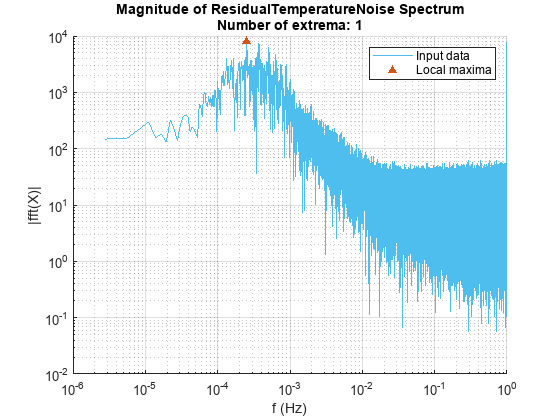


%plot fft of TimeTemp.ResidualTemperatureNoise
mag_fft = abs(Y_fft);
% Find local maxima
maxIndices = islocalmax(mag_fft,"MinSeparation",100,"SamplePoints",Hz,"MaxNumExtrema",1);

% Display results
figure();
hold on
plot(Hz,mag_fft,"SeriesIndex",6,"DisplayName","Input data")

% Plot local maxima
scatter(Hz(maxIndices),mag_fft(maxIndices),"^","filled","SeriesIndex",2,"DisplayName","Local maxima")
title({"Magnitude of ResidualTemperatureNoise Spectrum","Number of extrema: " + nnz(maxIndices)})
hold off;grid on;
legend
xlabel("f (Hz)");ylabel("|fft(X)|");
set(gca,'XScale','log','YScale','log');

%xlim([0 0.5]);

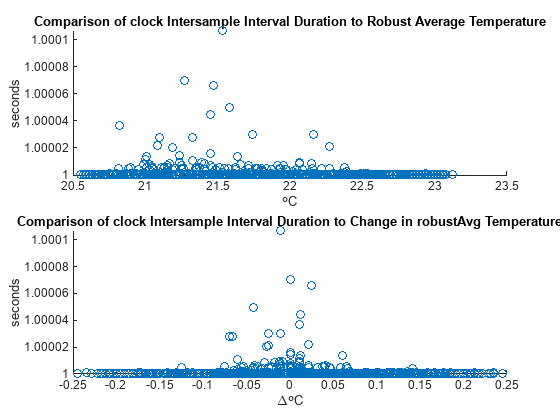

%plot dtime over Temp
%plot dtime over dTemp
figure()

subplot(2,1,1)
scatter(TimeTemp.robustAvg(2:end),dt)
title("Comparison of clock Intersample Interval Duration to Robust Average Temperature")
xlabel('\circC');ylabel('seconds');

subplot(2,1,2)
scatter(TimeTemp.TemperatureChange(2:end),dt)
title("Comparison of clock Intersample Interval Duration to Change in robustAvg Temperature")
xlabel('\Delta\circC');ylabel('seconds');

toc

Elapsed time is 222.043034 seconds.


plotselect = 0;
if plotselect > 0
    figure()
    hold off
    if plotselect == 1 | plotselect == 3
        dotsize = 4;
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp1"},dotsize,"filled")
        hold on
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp2"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp3"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp4"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp5"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp6"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp7"},dotsize,"filled")
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"Temp8"},dotsize,"filled")
        
    end
    if plotselect == 2 | plotselect == 3
        scatter(TimeTemp{:,"Days"},TimeTemp{:,"robustAvg"})
    end
    hold off
    legend()
    %ylim([20.5 22.5])
    datetick('x', 'HH:MM:SS');   % or 'yyyy-mm-dd HH:MM:SS'
    xlabel('Time');
    ylabel('Temperature (\circC)');
    grid on
end
toc

Elapsed time is 222.321495 seconds.


channels = [allsensors,"median","robustAvg","robustAvgSmoothGauss","ResidualTemperatureNoise"]

channels = 1×12 string array
    "Temp1"    "Temp2"    "Temp3"    "Temp4"    "Temp5"    "Temp6"    "Temp7"    "Temp8"    "median"    "robustAvg"    "robustAvgSmoothGauss"    "ResidualTemperatureNoise"


sensorData=TimeTemp{:,channels}; %Samples Sensor
taufull = unique(round(2.^(0:0.01:log2(size(sensorData,1)/2))));
%taufull = 1:height(sensorData)/2;
time0=toc

time0 = 222.4008

avarfull=allanvar(sensorData,taufull); % tau channel
time1=toc

time1 = 240.8835

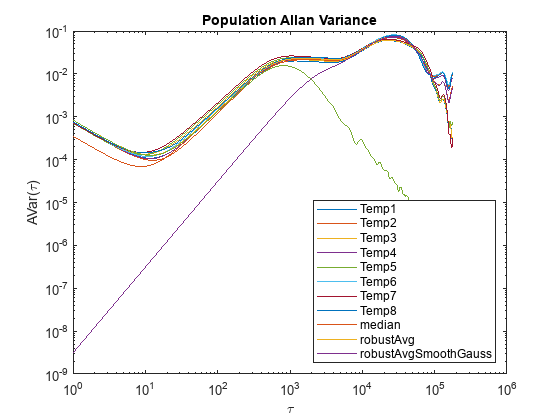


figure();loglog(taufull,avarfull);
xlabel('\tau');ylabel('AVar(\tau)');title("Population Allan Variance")
legend([allsensors,"median","robustAvg","robustAvgSmoothGauss"],"Location","southeast")

toc

Elapsed time is 241.054530 seconds.


%Rolling ALLAN on the data
maxtau=30;minpartitions = 3;
maxpts = maxtau*minpartitions; %seconds of window
windowpoints = 0:maxpts-1;
tau = [1,2,4,5,8,10,15,20,30];%intervals on the binary then to every 5 seconds
%tau=1:maxtau;%unique(round(2.^(0:0.01:log2(maxpts/2))));
seconds=height(sensorData)-maxpts;

avar = zeros([length(channels) seconds length(tau) ]);
linearFits = zeros([length(channels) seconds 2 ]);
quadFits = zeros([length(channels) seconds 3 ]);

slices = 1:seconds;
for c = 1:length(channels)
    for i = slices
        window = sensorData(i+windowpoints,c);
        % linear fit, quadratic Fit  there may be a correlation between the
        % velocity or acceleraion of the window and the Allan Variance
        linearFits(c,i,:) = polyfit(windowpoints, window, 1);
        quadFits(c,i,:) = polyfit(windowpoints, window, 2);
        avar(c,i,:) = allanvar(window,tau);
    end
end
size(avar)%avar(channel,slices,tau)

ans =           12      359910           9


%  the slices by their minimum tau and amplitude
[minAvar,minidx]=min(avar,[],3);
[maxAvar,maxidx]=max(avar,[],3);
avarT=table(avar,minAvar,minidx,maxAvar,maxidx,linearFits,quadFits);
% clear avar minAvar minidx maxAvar maxidx linearFits quadFits;
avarT.Properties.RowNames = channels

avarT = 12×7 table
                                      avar               minAvar            minidx             maxAvar            maxidx            linearFits            quadFits     
                                _________________    _______________    _______________    _______________    _______________    _________________    _________________

    Temp1                       1×359910×9 double    1×359910 double    1×359910 double    1×359910 double    1×359910 double    1×359910×2 double    1×359910×3 double
    Temp2                       1×359910×9 double    1×359910 double    1×359910 double    1×359910 double    1×359910 double    1×359910×2 double    1×359910×3 double
    Temp3                   

toc

Elapsed time is 631.976375 seconds.


selected_channel = "Temp1"

selected_channel = "Temp2"

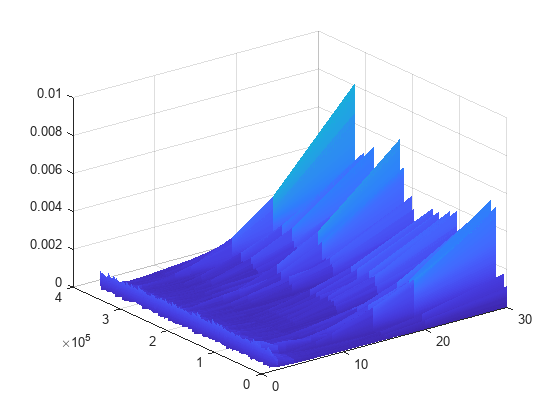

selected_channel = "Temp3"

selected_channel = "Temp4"

selected_channel = "Temp5"

selected_channel = "Temp6"

selected_channel = "Temp7"

selected_channel = "Temp8"

selected_channel = "median"

selected_channel = "robustAvg"

selected_channel = "robustAvgSmoothGauss"

selected_channel = "ResidualTemperatureNoise"

[TIME,TAU] = meshgrid(tau,slices);
%Create a surface with the minimum of each point is marked
for selected_channel = channels
    figure()
    selected_channel
    surf(TIME, TAU, log10(squeeze(avarT.avar(1,:,:))), 'EdgeColor','none');
    hold('on');
%scatter3(slices,tau(avar_sen.minidx),log10(avar_sen.minAvar));
%scatter3(slices,tau(avar_sen.maxAvar),log10(avar_sen.maxAvar));
hold('off');
set(gca,'YScale','log');
xlabel('Window index');ylabel('\tau');zlabel('log_{10}(\sigma(\tau))');
title('Rolling Allan Deviation Surface ');
colormap turbo;colorbar;
clim([min(log10(avarT.avar),[],"all") max(log10(avarT.avar),[],"all")]);
view(-37.5,30);%Az El
%window = [4.285E+4 42938]
end





%xlim(window)
%figure()
%subplot(2,1,1);scatter(slices,log10(avar_sen{:,"minAvar"}));set(gca,'YScale','log');
% xlabel('Window index');ylabel('log_{10}(\sigma(\tau))');%minimum of each point
%subplot(2,1,2);scatter(slices,log10(avar_sen{:,"maxAvar"}));set(gca,'YScale','log');
% xlabel('Window index'); ylabel('log_{10}(\sigma(\tau))');%maximum of each point

% figure()
% subplot(2,1,1)
% scatter(slices,tau(avar_sen.minidx));
% %xlim(window);
% xlabel('index');ylabel('\tau');title('Minimum Rolling Allan Deviation \tau')
% 
% subplot(2,1,2)
% scatter(TimeTemp{:,"Days"},TimeTemp{:,"robustAvg"});
% datetick('x', 'HH:MM:SS');   % or 'yyyy-mm-dd HH:MM:SS'
% xlabel('Time');ylabel('Temperature (°C)');
% grid on
toc


%Select a channel
selector=2;
selected_channel = channels(selector)
ChannelData   = TimeTemp{:,selected_channel};

% % Global Hadamard Variance
% N   = length(ChannelData);
% Htau = 1:floor(N/3);          % in samples; map to seconds if you want
% Hvar = zeros(size(Htau));
% 
% for i = 1:length(Htau)
%     m = Htau(i);
%     idxMax = N - 2*m;
%     d2 = ChannelData(1+m:idxMax+m) - 2*ChannelData(1:idxMax) + ChannelData(1+2*m:idxMax+2*m);
%     Hvar(i) = mean(d2.^2) / 6;
% end
% 
% loglog(Htau, Hvar); grid on;
% xlabel('\tau (samples)'); ylabel('\sigma_H^2(\tau)');
% title('3-point Hadamard variance of robustAvg');
% toc

% rolling AVAR Cross Section of the unsmoothed average
figure()
plot(tau, avarT.avar(1,:,:))
xlabel('\tau');
ylabel('Allan variance');

%legend("T1","T2","T3","T4","T5","T6","T7","T8","RA","Location","northwest");
set(gca,'XScale','log','YScale','log');
toc

figure();
subplot(2,1,1);scatter(avarT.minidx,avarT.linearFits(:,1));
xlabel('minAvar tau');ylabel('linear fit - slope');title('Linear fit Slope over Rolling Allan Deviation minimum \tau ')
subplot(2,1,2);scatter(avarT.minidx,avarT.linearFits(:,2));
xlabel('minAvar tau');ylabel('linear fit - intercept');title('Linear fit Intercept over Rolling Allan Deviation minimum \tau ')

figure();
subplot(3,1,1);scatter(avarT.minidx,avarT.quadFits(:,1));
xlabel('minAvar tau');ylabel('linear fit - acceleration');title('quadratic fit acceleration over Rolling Allan Deviation minimum \tau ')
subplot(3,1,2);scatter(avarT.minidx,avarT.quadFits(:,1));
xlabel('minAvar tau');ylabel('linear fit - slope');title('quadratic fit slope over Rolling Allan Deviation minimum \tau ')
subplot(3,1,3);scatter(avarT.minidx,avarT.quadFits(:,1));
xlabel('minAvar tau');ylabel('linear fit - intercept');title('quadratic fit intercept over Rolling Allan Deviation minimum \tau ')


k = 30000;
figure()
imagesc(slices, tau, log10(avarT.avar)');
set(gca,'YDir','normal','YScale','linear');
clim([min(log10(avarT.avar),[],"all") max(log10(avarT.avar),[],"all")]);
xlabel('Window index');
ylabel('\tau');
colorbar;
title('Rolling Allan Deviation');

hold on;
%scatter(slices,tau(avar_sen.minidx));
% mask=log10(avar_sen.minAvar)<-25;
% scatter(slices(mask),tau(avar_sen.minidx(mask)));

xline(k, 'w-', 'LineWidth', 2);   % white vertical hairline
hold off;

figure()
scatter(tau, avarT.avar(k,:));
xlabel('\tau');ylabel('Allan Variance');
set(gca,'XScale','log','YScale','log');
grid('on')
toc

%Compute the Per Tau FFT
Fs = 1;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(slices);             % Length of signal
Hz=Fs/L*(0:L-1);
Y_fft = fft(avarT.avar); %Rows are Time %columns are tau, 
%fft: If X is a matrix, then fft(X) treats the columns of X as vectors and returns the Fourier transform of each column.
toc

for fft_tau = [1 5 10 15 30]
    mag_fft = abs(Y_fft(:,fft_tau));
    % Find local maxima
    maxIndices = islocalmax(mag_fft,"MinSeparation",100,"SamplePoints",Hz,"MaxNumExtrema",1);
    
    % Display results
    figure();
    plot(Hz,mag_fft,"SeriesIndex",6,"DisplayName","Input data")
    hold on
    
    % Plot local maxima
    scatter(Hz(maxIndices),mag_fft(maxIndices),"^","filled","SeriesIndex",2,"DisplayName","Local maxima")
    title({"Complex Magnitude of fft Spectrum","Tau:"+fft_tau,"Number of extrema: " + nnz(maxIndices)})
    hold off;grid on;
    legend
    xlabel("f (Hz)");ylabel("|fft(X)|");
    set(gca,'XScale','log','YScale','log');
    %xlim([0 0.5]);
end
toc

figure();
surf(tau,Hz,log10(abs(Y_fft)),"EdgeColor","none");
xlabel("tau");ylabel("f (Hz)");zlabel("log10|fft(X)|");
set(gca,'XScale','linear','YScale','log','zscale','linear');
view(90+15,20);%Az El
ylim([0  0.5])
colorbar; 
%colormap turbo;
colormap parula;
toc

%Keeping this because I made it but this is absolutely pointless so far as I can tell

%Sort the slices by their minimum tau and amplitude
% avar_sen2 = sortrows(avar_sen,["minidx" "minAvar"]);

% k = 1000;
% figure()
% subplot(2,1,1)
% imagesc(slices, tau, log10(avar_sen2{:,1:30}'));
% set(gca,'YDir','normal','YScale','log');
% clim([min(log10(avar_sen2{:,1:30}'),[],"all") max(log10(avar_sen2{:,1:30}'),[],"all")]);
% xlabel('Window index');
% ylabel('\tau');
% colorbar;
% title('Rolling Allan Deviation');
% 
% hold on;
% scatter(slices,tau(avar_sen2{:,"minidx"}));
% xline(k, 'w-', 'LineWidth', 2);   % white vertical hairline
% hold off;
% 
% subplot(2,1,2)
% scatter(tau, avar_sen2{k,1:30});
% xlabel('\tau');ylabel('Allan Variance');
% set(gca,'XScale','log','YScale','log');
% grid('on')

% figure()
% subplot(2,1,2)
% scatter(slices,tau(avar_sen2{:,"minidx"}));
% %xlim(window);
% xlabel('index');ylabel('\tau');title('Minimum Rolling Allan Deviation \tau')
% subplot(2,1,1)
% surf(TIME, TAU, log10(avar_sen2{:,1:30}'), 'EdgeColor','none');
% hold('on');
% scatter3(slices,tau(avar_sen2{:,"minidx"}),log10(avar_sen2{:,"minAvar"}));
% % scatter3(slices,tau(avar_sen2{:,"maxAvar"}),log10(avar_sen2{:,"maxAvar"}));
% hold('off');
% set(gca,'YScale','log');xlabel('Window index');ylabel('\tau');zlabel('log_{10}(\sigma(\tau))');
% title('Rolling Allan Deviation Surface');
% colormap turbo;colorbar;
% view(20,70);


% xlim([4.292E4 4.293E4])
% ax = gca;
% chart = ax.Children(1);
% datatip(chart,42923,1.00245);
% 
% TimeTemp = TimeTemp(1:42923,:);
function kernel_dilated = VarKernelGenerator(order,tau)
    spacers = zeros([1 tau-1]);
    % Base finite-difference kernel from Pascal triangle
    k = pascal(order+1,1);
    k = flip(k(end,:));   % e.g., [1 -2 1] for order=2

    % Build dilated kernel
    kernel_dilated = [];
    for i = 1:length(k)
        kernel_dilated = [kernel_dilated k(i) spacers];
    end
    % Remove trailing zeros
    kernel_dilated = kernel_dilated(1:end-(tau-1));% row vector
end
function var = allanVarCustom(x, taus)
    var = zeros(size(taus));
    kernels = cell(size(taus));
    % Build dilated Allan kernel
    for i = 1:length(taus)
        kernels{i} = VarKernelGenerator(2, taus(i));
    end
    for i = 1:length(taus)
        % Convolution gives second difference at spacing tau
        d2 = conv(x, kernels{i}, 'valid');

        % Allan variance definition
        var(i) = mean(d2.^2) / 2;
    end
end

% function var = allanVarCustom(x, taus)
%     var = zeros(size(taus));    
%     for i = 1:length(taus)
%         tau = taus(i);
%         % Convolution gives second? difference at spacing tau
%         d2 = x(1:end-tau)-x(1+tau:end);
%         % Allan variance definition
%         var(i) = mean(d2.^2) / 2;
%     end
% end
function var = hadamardVarCustom(x, taus)
    var = zeros(size(taus));    
    for i = 1:length(taus)
        tau = taus(i);
        % Convolution gives fourth? difference at spacing tau
        d3 = x(1:end-2*tau) - 2*x(1+tau:end-tau) + x(1+2*tau:end);
        % d4 = -x(1:end-3*tau) + 3*x(1+tau:end-2*tau) - 3*x(1+2*tau:end-tau) + x(1+3*tau:end);
        % hadamard variance definition
        var(i) = mean(d3.^2) / 6;
    end
end

function var = allanVarVectorized(x, taus)
    taus = taus(:)';          % row vector
    T = max(taus);
    N = length(x);

    % Build index matrices
    i0 = (1:N-2*T)';          % base indices
    i1 = i0 + taus;           % +tau
    i2 = i0 + 2*taus;         % +2*tau

    % Slice x
    X0 = x(i0);               % [M × 1]
    X1 = x(i1);               % [M × numTaus]
    X2 = x(i2);               % [M × numTaus]

    % Allan differences
    d2 = X0 - 2*X1 + X2;

    % Allan variance
    var = mean(d2.^2, 1) / 2;
end
